#  Speech processing project

clc
clear
close all

## Data acquisition

[siren, Fs] = audioread("projectDSP.wav");
%sound(siren);
%pause(10);

## Fourier Transform and PSD calculations

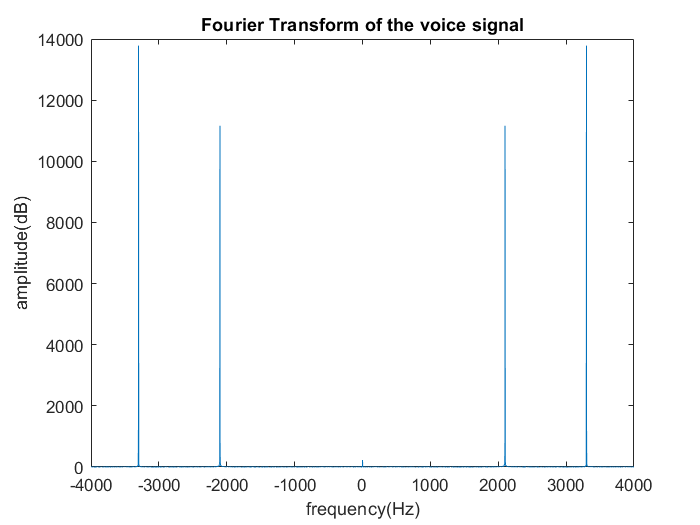

freq_siren = fftshift(fft(siren));
freq_siren_Mag = abs(freq_siren);

% deletes the insignificant parts of the data 
freq_siren(freq_siren_Mag < 1e-6) = 0;
phase_siren = unwrap(angle(freq_siren));

% defines the frequency axis
freq = (-length(freq_siren)/2 : length(freq_siren)/2 - 1)/ (length(freq_siren)/Fs);

figure(1)
plot(freq, freq_siren_Mag);
title("Fourier Transform of the voice signal")
xlabel("frequency(Hz)")
ylabel("amplitude(dB)")

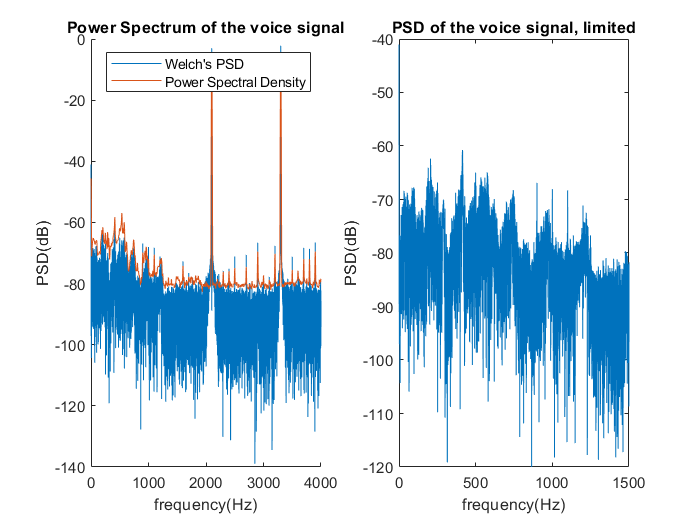

% gets you the PSD in two different manners
% Welch's PSD has more details but the pspectrum() function
% gives you a thorough understanding of the real en

[psd_siren_welch, f_welch] = pwelch(siren, length(freq), 10000, length(freq), Fs);
[psd_siren, f] = pspectrum(siren, Fs);

figure(2)
subplot(1, 2, 1)
hold on
title("Power Spectrum of the voice signal")
xlabel("frequency(Hz)")
ylabel("PSD(dB)")
plot(f_welch,pow2db(psd_siren_welch));
plot(f,pow2db(psd_siren));
hold off
legend("Welch's PSD", "Power Spectral Density")


subplot(1, 2, 2)
plot(f_welch,10*log10(psd_siren_welch));
title("PSD of the voice signal, limited")
xlabel("frequency(Hz)")
ylabel("PSD(dB)")
xlim([0 1500])
ylim([-120 -40 ])

#### As it can be seen, the content of the voice spectrum doesn't seem to have much information around 4000 Hz. Hence we apply a low pass filter to eliminate the frequencies after 3885 Hz.

#### After careful examinations I came to the conclusion that a great deal of noise is echoed through frequency domain in some harmonics of 100Hz. So the application of a bandstop filter came in handy here. Hence, many Notch-like filters that are shifted versions of the one below are applied:

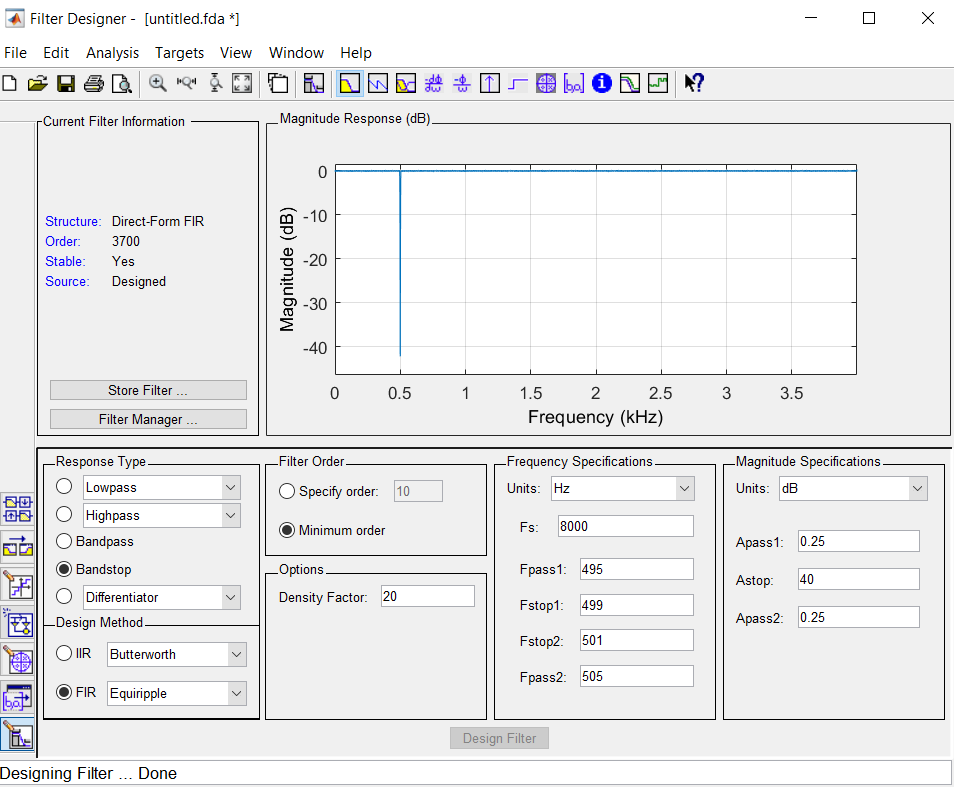

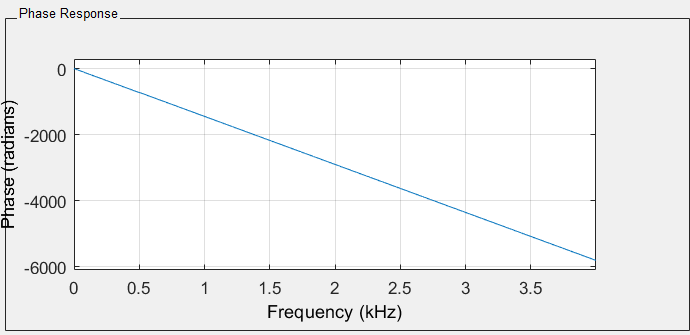

#### Based on a berief research on human voice, I found out the frequencies lower than 200 Hz can not contain much of human voice. so I also applied a high pass filter of below characteristics:

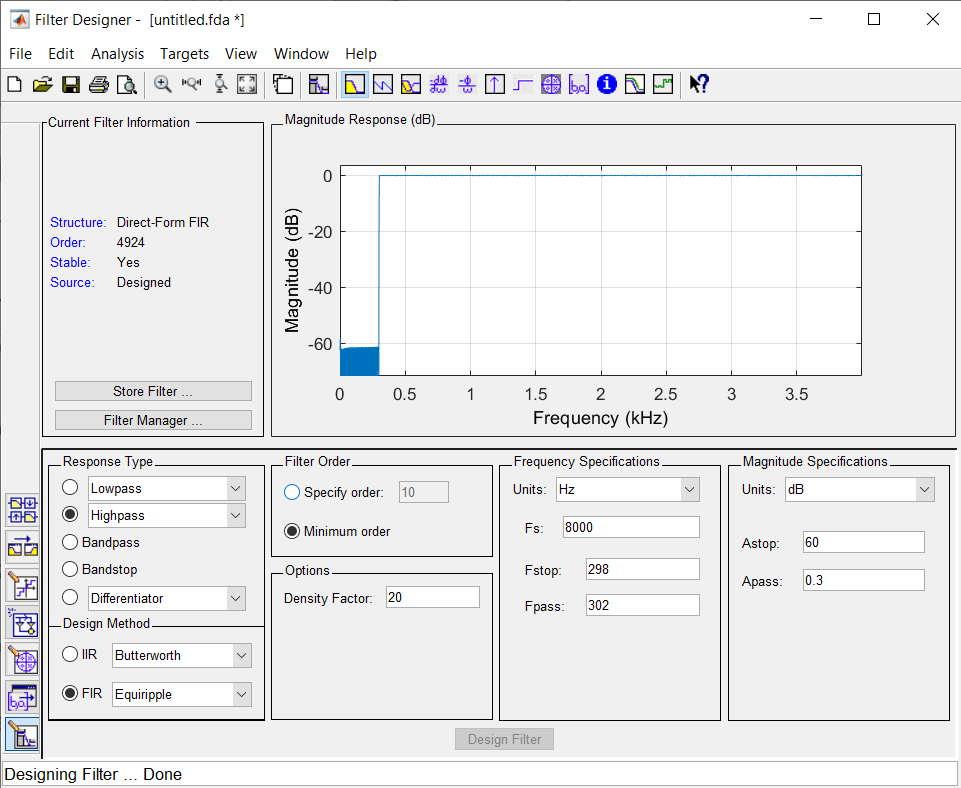

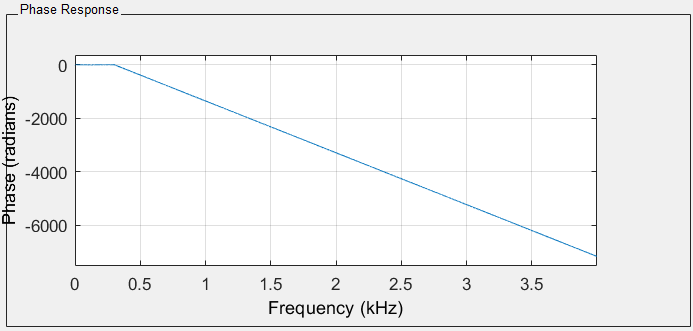

#### Here are the codes to apply these filters on our original signal:

% LP filtering

load("LPF_3885Hz.mat")
LPF_3885 = stop_3885

LPF_3885 =     0.0038    0.0011   -0.0009    0.0008   -0.0006    0.0005   -0.0004    0.0003   -0.0002    0.0002   -0.0001    0.0001   -0.0000   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0002   -0.0002    0.0002   -0.0002    0.0002   -0.0002    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0001    0.0001


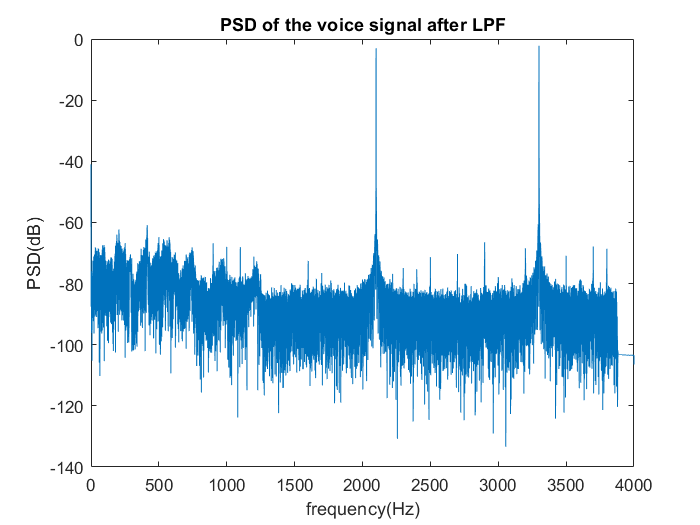

siren_1 = conv(siren, LPF_3885);

[psd_siren_1, f_1] = pwelch(siren_1, length(freq), 10000, length(freq), Fs);

figure(3)
plot(f_1,10*log10(psd_siren_1));
title("PSD of the voice signal after LPF")
xlabel("frequency(Hz)")
ylabel("PSD(dB)")

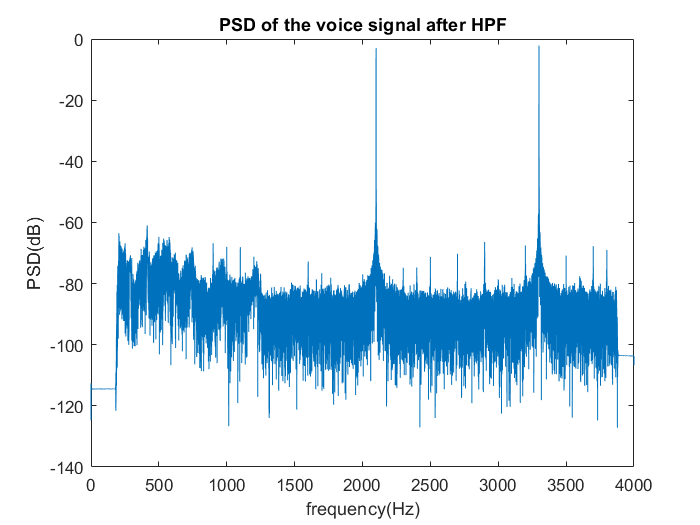

% HP filtering

load("HPF_200Hz.mat")
HPF_200 = HPF;
siren_2 = conv(siren_1, HPF_200);
[psd_siren_2, f_2] = pwelch(siren_2, length(freq), 10000, length(freq), Fs);

figure(4)
plot(f_2,10*log10(psd_siren_2));
title("PSD of the voice signal after HPF")
xlabel("frequency(Hz)")
ylabel("PSD(dB)")

#### Deleting contents around some harmonics of 100 Hz as they showed to be sinusoidal noises, echoed through spectrum.

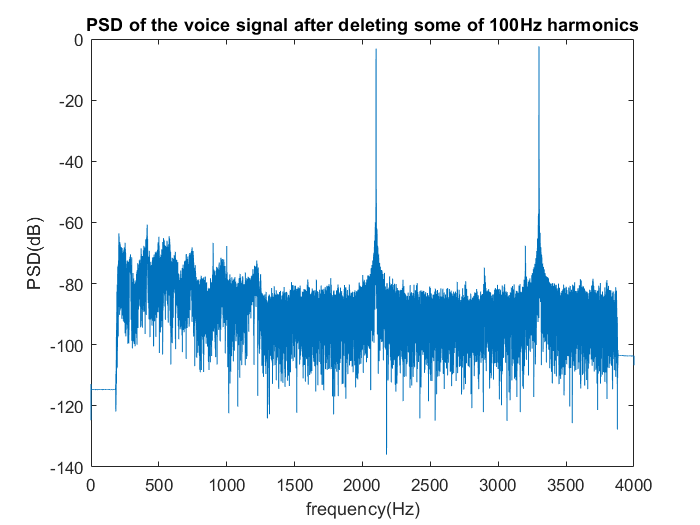


load("Notch_1100Hz.mat");
load("Notch_1200Hz.mat");
load("Notch_1300Hz.mat");
load("Notch_1400Hz.mat");
load("Notch_1600Hz.mat");
load("Notch_1700Hz.mat");
load("Notch_1900Hz.mat");
load("Notch_2300Hz.mat");
load("Notch_2400Hz.mat");
load("Notch_2500Hz.mat");
load("Notch_2700Hz.mat");
load("Notch_2800Hz.mat");
load("Notch_2900Hz.mat");
load("Notch_3000Hz.mat");
load("Notch_3100Hz.mat");
load("Notch_3500Hz.mat");
load("Notch_3600Hz.mat");
load("Notch_3700Hz.mat");
load("Notch_3800Hz.mat");

filter_bank = [
               stop_1100; stop_1200; stop_1300; stop_1400; stop_1600;
               stop_1700; stop_1900; stop_2300; stop_2400; stop_2500; 
               stop_2700; stop_2800; stop_2900; stop_3000; stop_3100;
               stop_3500; stop_3600; stop_3700; stop_3800
               ];

for i = 1 : 19
    siren_3 = conv(siren_2, filter_bank(i, :), "same");
    siren_2 = siren_3;
end  


[psd_siren_3, f_3] = pwelch(siren_3, length(freq), 10000, length(freq), Fs);

figure(5)
plot(f_3,10*log10(psd_siren_3));
title("PSD of the voice signal after deleting some of 100Hz harmonics")
xlabel("frequency(Hz)")
ylabel("PSD(dB)")

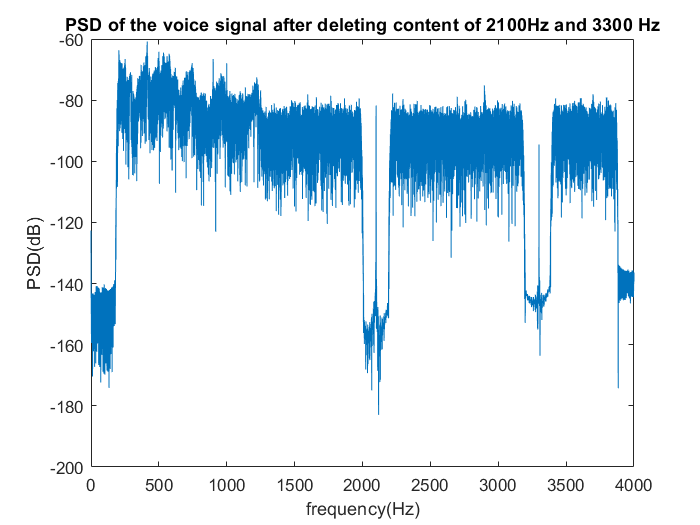

load("Notch_2100Hz.mat");
stop_2100Hz = stop_2100;
siren_4 = conv(siren_3, stop_2100Hz);

siren_5 = conv(siren_4, stop_2100Hz);

load("Notch_3300Hz.mat");
stop_3300Hz = stop_3300;
siren_6 = conv(siren_5, stop_3300Hz);

siren_7 = conv(siren_6, stop_3300Hz);

%sound(20*siren_7);


[psd_siren_line, f_line] = pwelch(siren_7, length(freq), 10000, length(freq), Fs);

figure(6)
plot(f_line, pow2db(psd_siren_line))
title("PSD of the voice signal after deleting content of 2100Hz and 3300 Hz")
xlabel("frequency(Hz)")
ylabel("PSD(dB)")

#### Truncation and normalization


startSample = 5000;
endSample = round(Fs * 7.9);
siren_7_truncated = siren_7(startSample:endSample);


#### "wdenoise" function smoothes the parts of spectrum that were dropped down so that the spectrum has a wholesome shape. however it gives a bad output, so it's been deleted


siren_8 = wdenoise(siren_7_truncated);

sound(10*siren_7_truncated);

pause(10);


#### The function "soundsc" normalizes the voice between [-1, 1] and amplifies it.

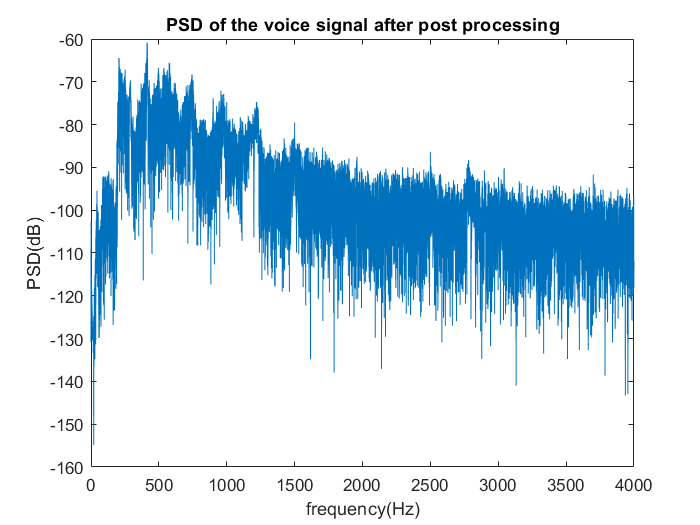

soundsc(10*siren_7_truncated);

[psd_siren_post_processed, f_post_processed] = pwelch(siren_8, length(siren_7_truncated), 10000, length(siren_7_truncated), Fs);

figure(7)
plot(f_post_processed, pow2db(psd_siren_post_processed))
title("PSD of the voice signal after post processing")
xlabel("frequency(Hz)")
ylabel("PSD(dB)")

This was indeed the best I could possibly do.